# Moving Average

To understand why the moving average procedure removes power at the tACS frequency and its harmonics, it is instructive to see the artifact estimation proces as a moving average filter. This filter has zeros everywhere except at sample points equally spaced with `1/tacsFrequency` samples between them. Artifact estimation is the convolution of this filter with the signal. Therefore its Fourier spectrum (the frequency response of the filter) shows what the filter will do in Fourier terms.

samplingRate  =10e3;          % Samples/s
tacsFrequency = 10;             % Hz
nrCyclesPerSegment = 30; % How many tACS cycles to use in each artifact segment
nrSegementsPerWindow = 10;
step                = 1;  % Take each neighboring segement (1) or skip this number of segments  (e.g., if the neural signal is epxected to have autocorrelation on this scale)
slide = false;
duration = step*nrCyclesPerSegment*nrSegementsPerWindow/tacsFrequency;

[v,t]= comb(duration,tacsFrequency,nrCyclesPerSegment,step,samplingRate,slide);
highCutOff = 50;

## Show filter and its amplitude spectrum

[~,ax]= fig('name',"MAFilter",'nrRows',2,'PaperCols',2);

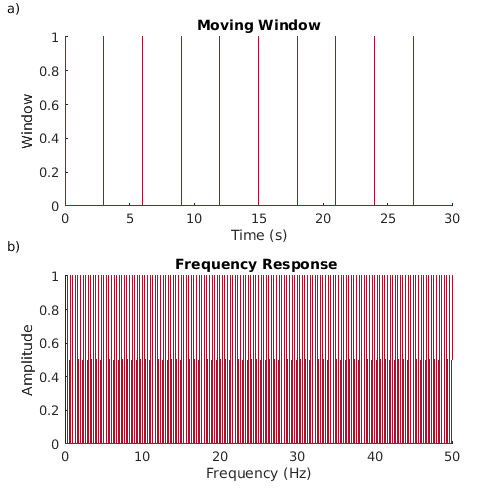

axes(ax(1))
plot(t/samplingRate,v)
xlabel('Time (s)')
ylabel 'Window'
title 'Moving Window'

axes(ax(2))
[a,freq] = fftReal(v,samplingRate);
a= abs(a)./(numel(v)/2);
a(1)=0;
plot(freq,a./max(a))
xlabel 'Frequency (Hz)'
ylabel 'Amplitude'
title('Frequency Response ');
set(gca,'XLim',[0 highCutOff])

## Windowing Artifact

Same problem, just a different window than above.

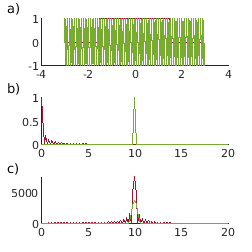

duration = nrCyclesPerSegment/tacsFrequency;
nrSamplesPerSegment = duration*samplingRate;
t = (-duration:1/samplingRate:duration-1/samplingRate)';
window = zeros(size(t));
window(abs(t)<0.5*duration)=1;
[ftWindow,freq] = fftReal(window,samplingRate);
ftWindow = abs(ftWindow);
ftWindow= ftWindow./max(ftWindow);
signal = sin(2*pi*tacsFrequency*t);
ftSignal = fftReal(signal,samplingRate);
ftSignal = abs(ftSignal);
ftSignal = ftSignal/max(ftSignal);

[~,ax]= fig('name',"WindowedFT",'nrRows',3);
axes(ax(1))
plot(t,window);
hold on
plot(t,signal);

axes(ax(2))
plot(freq,ftWindow);
hold on
plot(freq,ftSignal);
set(gca,'XLim',[0 2*tacsFrequency])

axes(ax(3))
ft =  fftReal(signal.*window,samplingRate);
ft = sqrt(ft.*conj(ft))/2;

hannWindow = [zeros(nrSamplesPerSegment/2,1) ;hann(nrSamplesPerSegment) ;zeros(nrSamplesPerSegment/2,1)];

ftH =  fftReal(signal.*hannWindow,samplingRate);
ftH = sqrt(ftH.*conj(ftH))/2;

plot(freq,ft)
hold on
plot(freq,ftH)



set(gca,'XLim',[0 2*tacsFrequency])

function [v,t]= comb(duration,f,nrCycles,step,samplingRate,slide)
t = (0:duration*samplingRate-1)';
nrSamplesPerCycle = round(samplingRate/f);
nrSamples = nrSamplesPerCycle*nrCycles;
v = zeros(size(t));
v(1:nrSamples*step:end)=1;
if slide
    orgV =v;
    for i=1:nrCycles-1
        v = v + circshift(orgV,i*nrSamplesPerCycle);
    end
end
end